%{
----- Modify Simulink to these specifications -----
PID, PI, and P manually tuning feedback control with disturbance
1. Coolant temperature and dilution rate step
2. No feed glucose concentration and coolant flowrate step
3. No feedforward (multicomponent switch 2)
%}

for ii = [6757.725 100 10 1]
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(2));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(2));

set_param("CSTR_Bioreactor_2023_FeedForward/PI_glucose", "P", num2str(ii));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
yline(40,"--","Set point")
legend("K_c Cohen Coon","K_c = 100","K_c = 10", "K_c = 1","Location","southwest")

% xline(500,"--b")
% yline(40,"--")
% legend("PI","PI","P","Disturbance","Set point","Location","Best")

xlim([450,1000])
% ylim([25,50])


title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

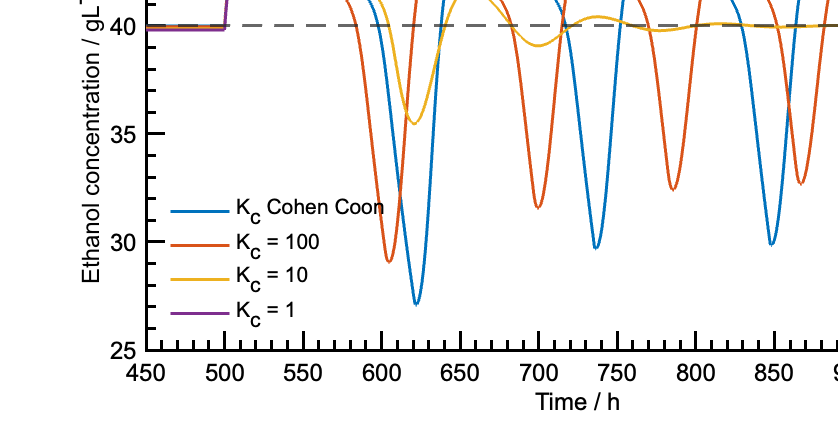

exportgraphics(gcf,"figures/ManualFeedback_PI_WithDisturbance_Dilution_Ethanol.pdf") 
hold off

for ii = [10 8 6 4 2]
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(2));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(2));

set_param("CSTR_Bioreactor_2023_FeedForward/PI_glucose", "P", num2str(ii));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
yline(40,"--","Set point")
legend("K_c = 10","K_c = 8", "K_c = 6", "K_c = 4", "K_c = 2","Location","southwest")

% xline(500,"--b")
% yline(40,"--")
% legend("PI","PI","P","Disturbance","Set point","Location","Best")

xlim([450,1000])
% ylim([25,50])


title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

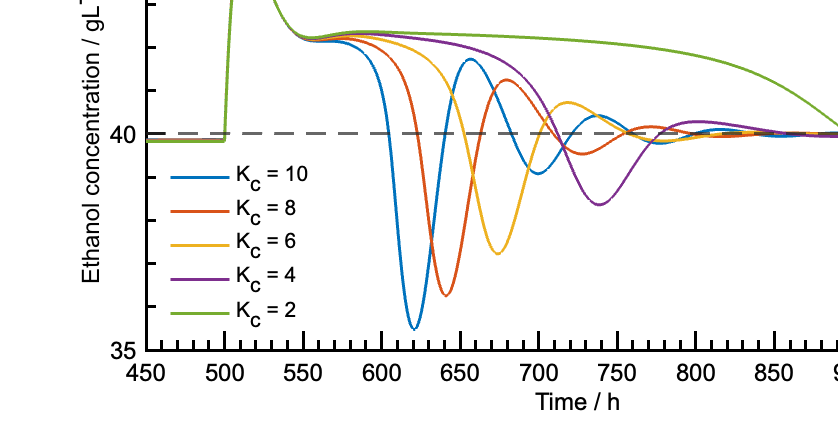

exportgraphics(gcf,"figures/ManualFeedback_PI_WithDisturbance_Dilution_Ethanol_Smaller.pdf") 
hold off

for ii = [8 7.5 7 6.5 6]
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(2));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(2));

set_param("CSTR_Bioreactor_2023_FeedForward/PI_glucose", "P", num2str(ii));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
yline(40,"--","Set point")
legend("K_c = 8","K_c = 7.5", "K_c = 7", "K_c = 6.5", "K_c = 6","Location","southwest")

% xline(500,"--b")
% yline(40,"--")
% legend("PI","PI","P","Disturbance","Set point","Location","Best")

xlim([450,1000])
% ylim([25,50])


title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

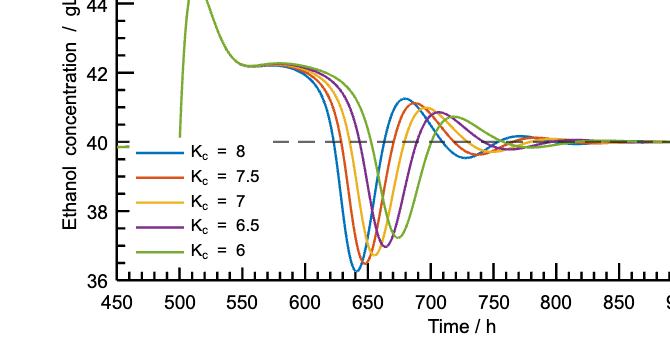

exportgraphics(gcf,"figures/ManualFeedback_PI_WithDisturbance_Dilution_Ethanol_SmallerSmaller.pdf") 
hold off